clear
M = load('StudentData/FeaturesM');
T = load('StudentData/FeaturesT');

4d data

training data

for sample = 1:300
TrainingDataClass0_4D(:,sample) = ...
[M.Data(sample).Normal.Area,M.Data(sample).Normal.Orientation,...
M.Data(sample).Normal.MajorAxisLength,M.Data(sample).Normal.MinorAxisLength];
TrainingDataClass1_4D(:,sample) = ...
[T.Data(sample).Normal.Area,T.Data(sample).Normal.Orientation,...
T.Data(sample).Normal.MajorAxisLength,T.Data(sample).Normal.MinorAxisLength];
end

Testing data

Indices = randperm(300);

for sample = 1:150
TestingDataClass0_4D(:,sample) = ...
[M.Data(300+Indices(sample)).Normal.Area,M.Data(300+Indices(sample)).Normal.Orientation,...
M.Data(300+Indices(sample)).Normal.MajorAxisLength,M.Data(300+Indices(sample)).Normal.MinorAxisLength];
TestingDataClass1_4D(:,sample) = ...
[T.Data(300+sample).Normal.Area,T.Data(300+sample).Normal.Orientation,...
T.Data(300+sample).Normal.MajorAxisLength,T.Data(300+sample).Normal.MinorAxisLength];
end

for sample = 1:150
FinalTestClass0_4D(:,sample) = ...
[M.Data(300+Indices(sample+150)).Normal.Area,M.Data(300+Indices(sample+150)).Normal.Orientation,...
M.Data(300+Indices(sample+150)).Normal.MajorAxisLength,M.Data(300+Indices(sample+150)).Normal.MinorAxisLength];
FinalTestClass1_4D(:,sample) = ...
[T.Data(300+Indices(sample+150)).Normal.Area,T.Data(300+Indices(sample+150)).Normal.Orientation,...
T.Data(300+Indices(sample+150)).Normal.MajorAxisLength,T.Data(300+Indices(sample+150)).Normal.MinorAxisLength];
end


4d

training

for sample = 1:300
TrainingDataClass0_6D(:,sample) = ...
[M.Data(sample).Normal.Area,M.Data(sample).Normal.Orientation,...
M.Data(sample).Normal.MajorAxisLength,M.Data(sample).Normal.MinorAxisLength,...
M.Data(sample).Normal.ConvexArea,M.Data(sample).Normal.Perimeter];
TrainingDataClass1_6D(:,sample) = ...
[T.Data(sample).Normal.Area,T.Data(sample).Normal.Orientation,...
T.Data(sample).Normal.MajorAxisLength,T.Data(sample).Normal.MinorAxisLength...
T.Data(sample).Normal.ConvexArea,T.Data(sample).Normal.Perimeter];
end

testing

for sample = 1:150
TestingDataClass0_6D(:,sample) = ...
[M.Data(300+Indices(sample)).Normal.Area,M.Data(300+Indices(sample)).Normal.Orientation,...
M.Data(300+Indices(sample)).Normal.MajorAxisLength,M.Data(300+Indices(sample)).Normal.MinorAxisLength,...
M.Data(300+Indices(sample)).Normal.ConvexArea,M.Data(300+Indices(sample)).Normal.Perimeter];
TestingDataClass1_6D(:,sample) = ...
[T.Data(300+Indices(sample)).Normal.Area,T.Data(300+Indices(sample)).Normal.Orientation,...
T.Data(300+Indices(sample)).Normal.MajorAxisLength,T.Data(300+Indices(sample)).Normal.MinorAxisLength...
T.Data(300+Indices(sample)).Normal.ConvexArea,T.Data(300+Indices(sample)).Normal.Perimeter];
end

for sample = 1:150
FinalTestClass0_6D(:,sample) = ...
[M.Data(300+Indices(sample+150)).Normal.Area,...
M.Data(300+Indices(sample+150)).Normal.Orientation,...
M.Data(300+Indices(sample+150)).Normal.MajorAxisLength,...
M.Data(300+Indices(sample+150)).Normal.MinorAxisLength,...
M.Data(300+Indices(sample+150)).Normal.ConvexArea,...
M.Data(300+Indices(sample+150)).Normal.Perimeter];
FinalTestClass1_6D(:,sample) = ...
[T.Data(300+Indices(sample+150)).Normal.Area,...
T.Data(300+Indices(sample+150)).Normal.Orientation,...
T.Data(300+Indices(sample+150)).Normal.MajorAxisLength,...
T.Data(300+Indices(sample+150)).Normal.MinorAxisLength...
T.Data(300+Indices(sample+150)).Normal.ConvexArea,...
T.Data(300+Indices(sample+150)).Normal.Perimeter];
end

normalization

Means = abs(mean([TrainingDataClass0_4D,TrainingDataClass1_4D]'));

TrainingDataClass0_4D = TrainingDataClass0_4D./Means';
TrainingDataClass1_4D = TrainingDataClass1_4D./Means';
TestingDataClass0_4D=TestingDataClass0_4D./Means';
TestingDataClass1_4D=TestingDataClass1_4D./Means';

Means2 = abs(mean([TrainingDataClass0_6D,TrainingDataClass1_6D]'));

TrainingDataClass0_6D = TrainingDataClass0_6D./Means2';
TrainingDataClass1_6D = TrainingDataClass1_6D./Means2';
TestingDataClass0_6D=TestingDataClass0_6D./Means2';
TestingDataClass1_6D=TestingDataClass1_6D./Means2';


combination of net sizes

for i=1:10
    config(i,:)=[i,0,0];
    config(i+10,:)=[i,i,0];
    config(i+20,:)=[i,i,i];
end

repetitions=10;
[ErrorSum]=trainednetconfig(config(1:10,1),repetitions,TrainingDataClass0_4D,TrainingDataClass1_4D,TestingDataClass0_4D,TestingDataClass1_4D);
ErrorSum(:,11:20)=trainednetconfig(config(11:20,1:2),repetitions,TrainingDataClass0_4D,TrainingDataClass1_4D,TestingDataClass0_4D,TestingDataClass1_4D);
ErrorSum(:,21:30)=trainednetconfig(config(21:30,:),repetitions,TrainingDataClass0_4D,TrainingDataClass1_4D,TestingDataClass0_4D,TestingDataClass1_4D);

[ErrorSum2]=trainednetconfig(config(1:10,1),repetitions,TrainingDataClass0_6D,TrainingDataClass1_6D,TestingDataClass0_6D,TestingDataClass1_6D);
ErrorSum2(:,11:20)=trainednetconfig(config(11:20,1:2),repetitions,TrainingDataClass0_6D,TrainingDataClass1_6D,TestingDataClass0_6D,TestingDataClass1_6D);
ErrorSum2(:,21:30)=trainednetconfig(config(21:30,:),repetitions,TrainingDataClass0_6D,TrainingDataClass1_6D,TestingDataClass0_6D,TestingDataClass1_6D);

Performance stats

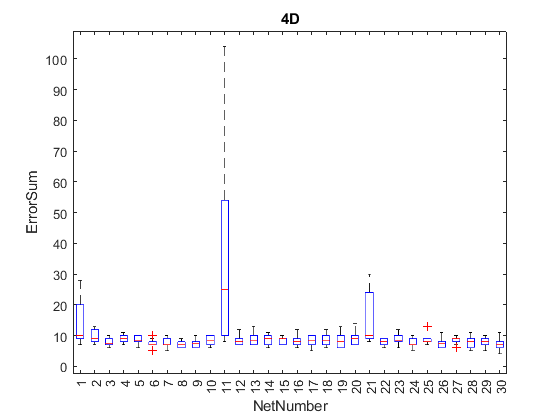

figure; boxplot(ErrorSum); ylabel('ErrorSum'); xlabel('NetNumber'); title('4D')

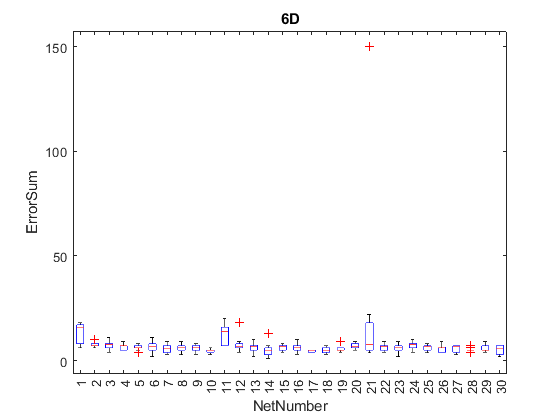

figure; boxplot(ErrorSum2); ylabel('ErrorSum'); xlabel('NetNumber'); title('6D')

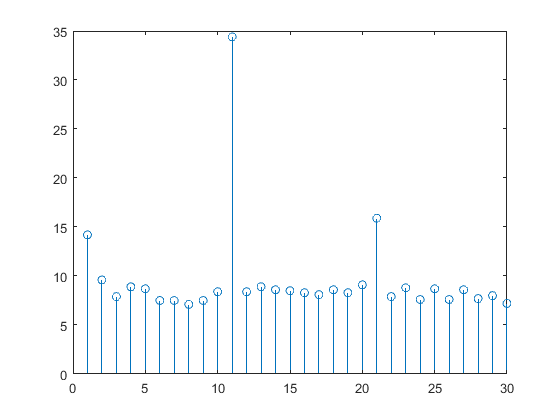

[~,n]=size(ErrorSum);
for i=1:n
    meanerror(i)=mean(ErrorSum(:,i));
    
end

[m,n]=size(ErrorSum2);
for i=1:n
    meanerror2(i)=mean(ErrorSum2(:,i));
end
stem(meanerror)

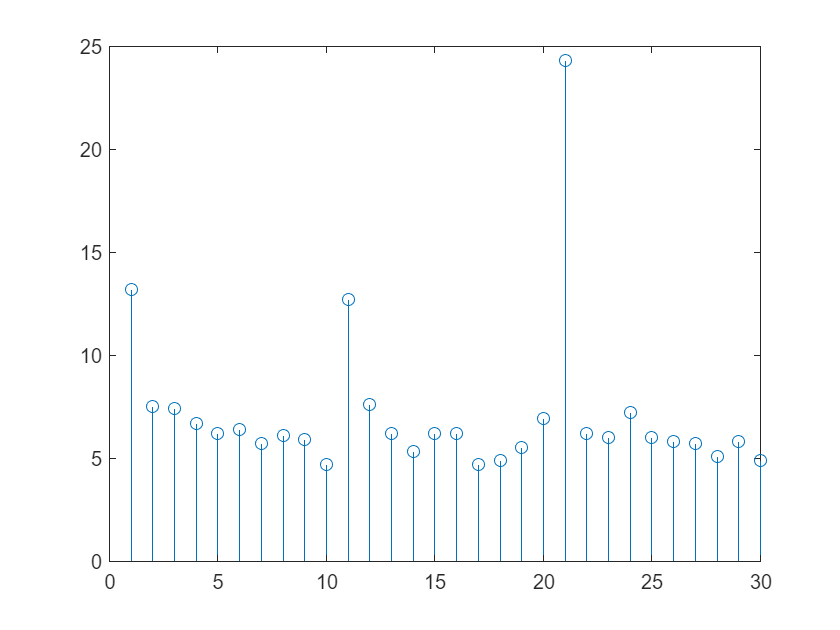

stem(meanerror2)


[val,loc]=min(meanerror)

val = 7.1000

loc = 8

[val2,loc2]=min(meanerror2)

val2 = 4.7000

loc2 = 10

bestconf=2*config(loc,:)

bestconf =     16     0     0


bestconf2=2*config(loc2,:)

bestconf2 =     20     0     0


% save config
% save ErrorSum4d ErrorSum
% save ErrorSum6d ErrorSum2

function [ErrorSum]=trainednetconfig(config,repetitions,TrainingDataClass0,TrainingDataClass1,TestingDataClass0,TestingDataClass1)


TargetTrain = [ones(1,300),zeros(1,300)];
TrainingData = [TrainingDataClass0,TrainingDataClass1];

TestSerie=0;


for nettype=1:length(config)
NetworkSize = config(nettype,:).*2; % Number of neurons in all the hidden layers

TestSerie=TestSerie+1;

for Test = 1:repetitions
OurNet = newff(TrainingData,TargetTrain,NetworkSize); % Net initialization
OurNet.TrainParam.time = 20; % Max time allowed
OurNet = train(OurNet,TrainingData,TargetTrain);
Results0 = sim(OurNet,TestingDataClass0);
Results1 = sim(OurNet,TestingDataClass1);
ErrorsA(Test,TestSerie) = sum([Results0<0.5]);
ErrorsD(Test,TestSerie) = sum([Results1>=0.5]);
ErrorSum(Test,TestSerie) = ErrorsD(Test,TestSerie)+ErrorsA(Test,TestSerie);
end
end
end